clc;
clear;
close all;

trainingDir = 'data\data_latih';
trainingSet = imageDatastore(trainingDir,'IncludeSubfolders', true, 'LabelSource', 'foldernames');
countEachLabel(trainingSet)

ans = 2×2 table
     Label      Count
    ________    _____

    Abnormal    5    
    Normal      5    


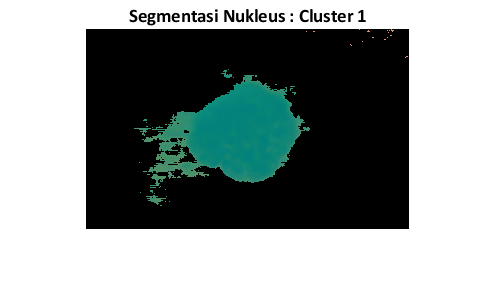

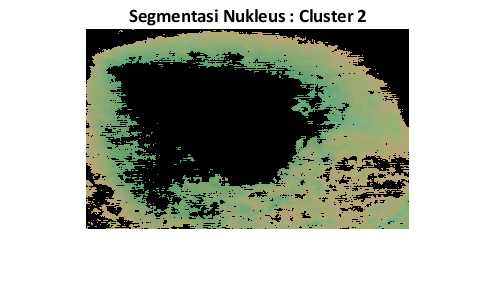

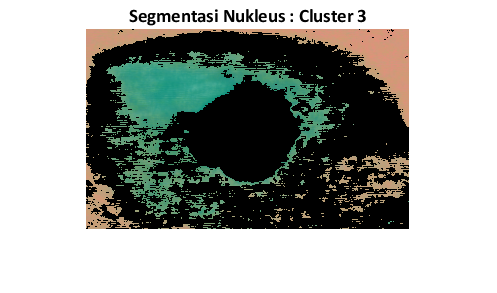

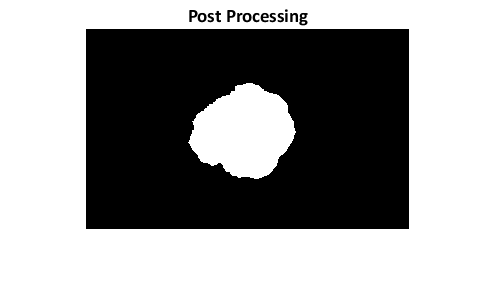

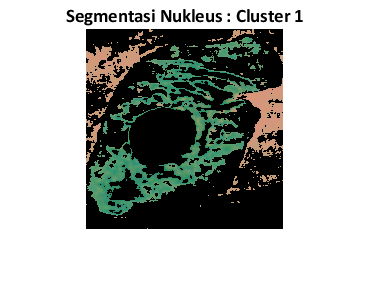

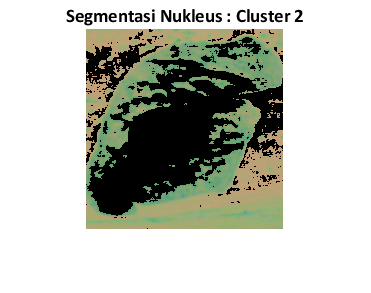

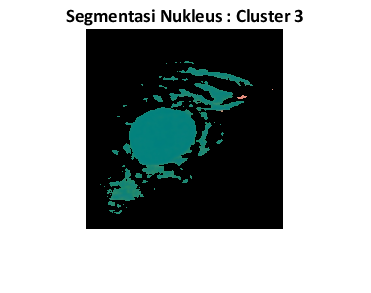

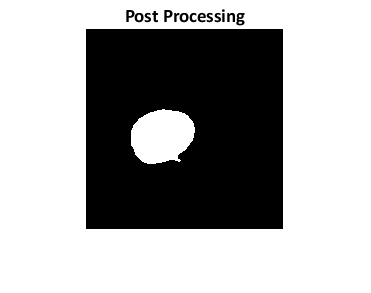

numImages = numel(trainingSet.Files);
smearTraining = zeros(numImages,4);

for i = 1:numImages
    img = readimage(trainingSet, i);
    % PRE-PROCESSING
    I = imresize(img, [200 NaN]);
    H = histeq(I);
    M = imgaussfilt3(H);
    
    %SEGMENTASI K-MEANS CLUSTERING
    cform = makecform('srgb2lab');
    lab_M = applycform(M,cform);
    nColorsSmear = 3;
    
    ab_smear = double(lab_M(:,:,2:3));
    smear_rows = size(ab_smear, 1);
    smear_cols = size(ab_smear, 2);
    ab_smear = reshape(ab_smear,smear_rows*smear_cols, 2);
    
    [cluster_idx, cluster_center] = kmeans(ab_smear, nColorsSmear, 'distance', 'sqEuclidean', 'Replicates', 3);
    pixel_labels = reshape(cluster_idx, smear_rows, smear_cols);
    
    segmented_images = cell(1,3);
    rgb_label = repmat(pixel_labels,[1,1,3]);
    
    for k = 1:nColorsSmear
        colors = lab_M; %I;
        colors(rgb_label ~= k) = 0;
        segmented_images{k} = colors;
        figure, imshow(segmented_images{k});title(['Segmentasi Nukleus : Cluster ', num2str(k)], 'FontName','Calibri','FontSize',14,'FontWeight','bold');
    end
    
    nilai_rata_cluster = mean(cluster_center,2);
    [tmp, idx] = sort(nilai_rata_cluster);
    cluster_smear = idx(1);
    
    L = M(:,:,1);
    smear_idx = find(pixel_labels == cluster_smear);
    L_smear = L(smear_idx);
    segment_smear = imbinarize(L_smear);
    
    smear_labels = repmat(uint8(0),[smear_rows smear_cols]);
    smear_labels(smear_idx(segment_smear==false)) = 1;
    smear_labels = repmat(smear_labels,[1 1 3]);
    nukleus_smear = I;
    nukleus_smear(smear_labels ~= 1) = 0;
    figure, imshow(nukleus_smear), title('Hasil Segmentasi K-Means', 'FontName','Calibri','FontSize',14,'FontWeight','bold');
    
    % POST-PROCESSING
    BW = rgb2gray(nukleus_smear);
    BW = im2bw(BW, graythresh(BW));
    BW = imfill(BW, 'holes');
    BW = imclearborder(BW);
    BW = bwmorph(BW,'erode',1);
    BW = bwareaopen(BW, 100);
    imshow(BW), title('Post Processing', 'FontName','Calibri','FontSize',14,'FontWeight','bold')
    
    % EKSTRAKSI FITUR
    [B,L] = bwboundaries(BW,'noholes');
    stats = regionprops(L,'BoundingBox','Centroid','Area','Perimeter','Eccentricity');
    hold on ;
    
    [m,n] = size(I);
    for k=1:length(B)
        boundary = B{k};
        Area = (stats(k).Area)/(m*n);
        Perimeter = (stats(k).Perimeter)/(2*(m+n));
        Eccentricity = stats(k).Eccentricity;
        Metric = 4*pi*Area/Perimeter^2;
    end
    
    % PEMBENTUKAN DATA LATIH
    smearTraining(i,1) = Area;
    smearTraining(i,2) = Perimeter;
    smearTraining(i,3) = Metric;
    smearTraining(i,4) = Eccentricity;
end

trainingLabels = trainingSet.Labels;
classifier = fitcecoc(smearTraining, trainingLabels)

classifier =   ClassificationECOC
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [Abnormal    Normal]
           ScoreTransform: 'none'
           BinaryLearners: {[1×1 classreg.learning.classif.CompactClassificationSVM]}
               CodingName: 'onevsone'


  Properties, Methods


save classifier classifier